# Underapproximative verification of stochastic LTI systems using Fourier transform and convex optimization

This example will demonstrate the use of SReachTools in verification and controller synthesis for stochastic continuous-state discrete-time linear time-invariant (LTI) systems.

Specifically, we will discuss the [terminal hitting-time stochastic reach-avoid problem](https://doi.org/10.1016/j.automatica.2010.08.006), where we are provided with a stochastic system model, a safe set to stay within, and a target set to reach at a specified time, and we will use SReachTools to solve the following problems:

- **Verification problem from an initial state: **Compute an [underapproximation of the maximum attainable reach-avoid probability given an initial state](https://doi.org/10.1109/LCSYS.2017.2716364),

- **Controller synthesis problem: **Synthesize a  [controller to achieve this probability](https://doi.org/10.1109/LCSYS.2017.2716364), and

- **Verification problem: **Compute a [polytopic underapproximation](https://doi.org/10.1145/3178126.3178148) of all the initial states from which the system can be driven to meet a predefined probabilistic safety threshold.

Our approach uses Fourier transforms, convex optimization, and gradient-free optimization techniques to compute a scalable underapproximation to the [terminal hitting-time stochastic reach-avoid problem](https://doi.org/10.1016/j.automatica.2010.08.006).

## Notes about this Live Script:

- **MATLAB dependencies**: This Live Script uses MATLAB's [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html), and [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

- **External dependencies**: This Live Script uses Multi-Parameteric Toolbox ([MPT](http://people.ee.ethz.ch/~mpt/3/)) and [CVX](http://cvxr.com/cvx/). 

- We will also [Genz's algorithm](http://www.math.wsu.edu/faculty/genz/software/matlab/qsimvnv.m) (included in helperFunctions of SReachTools) to evaluate integrals of a Gaussian density over a polytope.

- Make sure that `srtinit` is run before running this script.

This Live Script is part of the SReachTools toolbox. License for the use of this function is given in [https://github.com/unm-hscl/SReachTools/blob/master/LICENSE](https://github.com/unm-hscl/SReachTools/blob/master/LICENSE).

## Problem formulation: spacecraft rendezvous and docking problem

We consider both the spacecrafts, referred to as the deputy spacecraft and the chief spacecraft, to be in the same circular orbit. **We desire that the deputy reaches the chief at a specified time (the control time horizon) while remaining in a line-of-sight cone.** To account for the modeling uncertainties and unmodeled disturbance forces, we will use a stochastic model to describe the relative dynamics of the deputy satellite with respect to the chief satellite. 

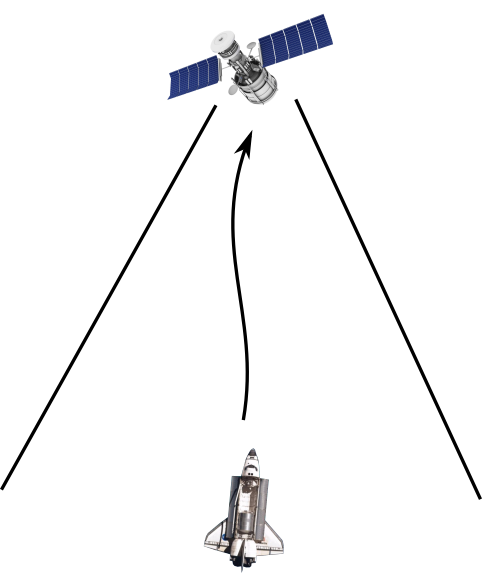

## Dynamics model for the deputy relative to the chief spacecraft

The relative planar dynamics of the deputy with respect to the chief are described by the [Clohessy-Wiltshire-Hill (CWH) equations](https://doi.org/10.1109/CDC.2013.6760626). Specifically, we have a LTI system describing the relative dynamics and it is perturbed by a low-stochasticity Gaussian disturbance to account for unmodelled phenomena and disturbance forces. We will set the thrust levels permitted to be within a origin-centered box of side $0.2$.

umax=0.1;
mean_disturbance = zeros(4,1);
covariance_disturbance = diag([1e-4, 1e-4, 5e-8, 5e-8]);
% Define the CWH (planar) dynamics of the deputy spacecraft relative to the chief spacecraft as a LtiSystem object
sys = getCwhLtiSystem(4,...
                      Polyhedron('lb', -umax*ones(2,1),...
                                 'ub',  umax*ones(2,1)),...
                      StochasticDisturbance('Gaussian',...
                                            mean_disturbance,...
                                            covariance_disturbance));

## Target set and safe set creation

For the formulation of the [terminal hitting-time stochastic reach-avoid problem](https://doi.org/10.1016/j.automatica.2010.08.006), 

- **the safe set** is the line-of-sight (LoS) cone is the region where accurate sensing of the deputy is possible (set to avoid is outside of this LoS cone), and 

- **the target set** is a small box around the origin which needs to be reached (the chief is at the origin in the relative frame). 

time_horizon=5;                                             % Stay within a line of sight cone for 4 time steps and 
                                                            % reach the target at t=5% Safe Set --- LoS cone
%% Safe set definition --- LoS cone |x|<=y and y\in[0,ymax] and |vx|<=vxmax and |vy|<=vymax
ymax=2;
vxmax=0.5;
vymax=0.5;
A_safe_set = [1, 1, 0, 0;           
             -1, 1, 0, 0; 
              0, -1, 0, 0;
              0, 0, 1,0;
              0, 0,-1,0;
              0, 0, 0,1;
              0, 0, 0,-1];
b_safe_set = [0;
              0;
              ymax;
              vxmax;
              vxmax;
              vymax;
              vymax];
safe_set = Polyhedron(A_safe_set, b_safe_set);
%% Target set --- Box [-0.1,0.1]x[-0.1,0]x[-0.01,0.01]x[-0.01,0.01]
target_set = Polyhedron('lb', [-0.1; -0.1; -0.01; -0.01],...
                        'ub', [0.1; 0; 0.01; 0.01]);
%% Target tube
target_tube = TargetTube('reach-avoid', safe_set, target_set, time_horizon);

## Problem 1 and 2: Verification and controller synthesis from a given initial state

We will first specify the initial state and parameters for the MATLAB's Global Optimization Toolbox `patternsearch`.

initial_state = [-0.75;         % Initial x relative position
                 -0.75;         % Initial y relative position
                 0;             % Initial x relative velocity
                 0];            % Initial y relative velocity
slice_at_vx_vy = initial_state(3:4);             
%% Parameters for MATLAB's Global Optimization Toolbox patternsearch
desired_accuracy = 1e-3;        % Decrease for a more accurate lower 
                                % bound at the cost of higher 
                                % computation time
%PSoptions = psoptimset('Display','off');

Next, using SReachTools, we will compute an [optimal open-controller and the associated reach-avoid probability](https://doi.org/10.1109/LCSYS.2017.2716364). This function takes about few minutes to run.

timer_point = tic;
% [lb_stochastic_reach_avoid, optimal_input_vector] = ...
%     getLowerBoundStochReachAvoid(sys,...
%         initial_state,...
%         target_tube,...
%         safe_set,...
%         'genzps',...
%         [],...
%         desired_accuracy,...
%         PSoptions); 
[lb_stochastic_reach_avoid, optimal_input_vector] = ...
    getLowerBoundStochReachAvoid(sys,...
        initial_state,...
        target_tube,...
        safe_set,...
        'cccpwl',...
        desired_accuracy); 
elapsed_time_pt = toc(timer_point);
fprintf(['Maximum reach-avoid probability using an open-loop controller: %1.3f\n' ...
         'Time taken for computing the underapproximative verification and controller synthesis: %1.3f s\n'],...
         lb_stochastic_reach_avoid,...
         elapsed_time_pt);

Maximum reach-avoid probability using an open-loop controller: 0.866
Time taken for computing the underapproximative verification and controller synthesis: 0.877 s


The function `getLowerBoundStochReachAvoid` uses [Fourier transform and convex optimization ](http://scalable technique ) to underapproximate the reach-avoid problem. Note that $\texttt{lb_stochastic_reach_avoid}$ is a lower bound to the maximum attainable reach-avoid probability since using a state-feedback law (also known as a Markov policy) can incorporate more information and attain a higher threshold of safety. Unfortuately, the current state-of-the-art approaches can compute a state-feedback law only using [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006) (intractable for a 4D problem) or provide [overapproximations](https://doi.org/10.1613/jair.5500) of safety (unsuitable for verification).

Using the computed optimal open-loop control law, we can compute the associated optimal mean trajectory.

[H_matrix, mean_X_sans_input, ~] =...
       getHmatMeanCovForXSansInput(sys,...
                                   initial_state,...
                                   time_horizon);
optimal_mean_X = mean_X_sans_input + H_matrix * optimal_input_vector;
optimal_mean_trajectory=reshape(optimal_mean_X,sys.state_dim,[])

optimal_mean_trajectory =    -0.6839   -0.5447   -0.3279   -0.1023    0.0001
   -0.7545   -0.7004   -0.5199   -0.2597   -0.0500
    0.0066    0.0074    0.0144    0.0082    0.0020
   -0.0005    0.0059    0.0121    0.0139    0.0071


## Visualization of the optimal mean trajectory and the safe and target sets

We can visualize this trajectory along with the specified safe and target sets using MPT3's plot commands.

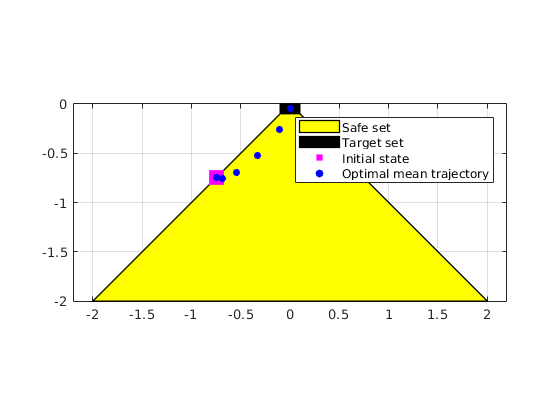

%% Plotting
figure();
box on;
hold on;
plot(safe_set.slice([3,4], slice_at_vx_vy), 'color', 'y');
plot(target_set.slice([3,4], slice_at_vx_vy), 'color', 'k');
scatter(initial_state(1),initial_state(2),200,'ms','filled');
scatter([initial_state(1), optimal_mean_trajectory(1,:)],...
        [initial_state(2), optimal_mean_trajectory(2,:)],...
        30, 'bo', 'filled');
legend_cell = {'Safe set','Target set','Initial state','Optimal mean trajectory'};
legend(legend_cell);
axis equal;

## Validate the open-loop controller and the obtained lower bound using Monte-Carlo simulations

%% Monte-Carlo simulation parameters
n_mcarlo_sims = 1e5;
n_sims_to_plot = 10;
% This function returns the concatenated state vector stacked columnwise
concat_state_realization = generateMonteCarloSims(...
                               n_mcarlo_sims,...
                               sys,...
                               initial_state,...
                               time_horizon,...
                               optimal_input_vector);
% Check if the location is within the target_set or not
mcarlo_result = target_tube.contains(concat_state_realization);
fprintf('Monte-Carlo simulation using %1.0e particles: %1.3f\n',...
        n_mcarlo_sims,...
        sum(mcarlo_result)/n_mcarlo_sims);

Monte-Carlo simulation using 1e+05 particles: 0.865


## Plotting random number of trajectories

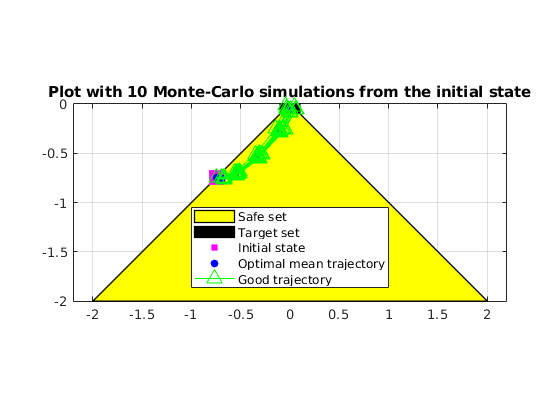

figure();
clf
box on;
hold on;
plot(safe_set.slice([3,4], slice_at_vx_vy), 'color', 'y');
plot(target_set.slice([3,4], slice_at_vx_vy), 'color', 'k');
scatter(initial_state(1),initial_state(2),200,'ms','filled');
scatter([initial_state(1), optimal_mean_trajectory(1,:)],...
        [initial_state(2), optimal_mean_trajectory(2,:)],...
        30, 'bo', 'filled');
legend_cell = {'Safe set','Target set','Initial state','Optimal mean trajectory'};
legend(legend_cell);
%% Plot n_sims_to_plot number of trajectories
green_legend_updated = 0;
red_legend_updated = 0;
traj_indices = floor(n_mcarlo_sims*rand(1,n_sims_to_plot));
for realization_index = traj_indices
    % Check if the trajectory satisfies the reach-avoid objective
    if mcarlo_result(realization_index)
        % Assign green triangle as the marker
        markerString = 'g^-';
    else
        % Assign red asterisk as the marker
        markerString = 'r*-';
    end
    % Create [x(t_1) x(t_2)... x(t_N)]
    reshaped_X_vector = reshape(concat_state_realization(:,realization_index), sys.state_dim,[]);
    % This realization is to be plotted
    h = plot([initial_state(1), reshaped_X_vector(1,:)], ...
             [initial_state(2), reshaped_X_vector(2,:)], ...
             markerString, 'MarkerSize',10);
    % Update the legends if the first else, disable
    if strcmp(markerString,'g^-')
        if green_legend_updated
            h.Annotation.LegendInformation.IconDisplayStyle = 'off';
        else
            green_legend_updated = 1;
            legend_cell{end+1} = 'Good trajectory';
        end
    elseif strcmp(markerString,'r*-')
        if red_legend_updated
            h.Annotation.LegendInformation.IconDisplayStyle = 'off';
        else
            red_legend_updated = 1;
            legend_cell{end+1} = 'Bad trajectory';
        end
    end
end    
legend(legend_cell, 'Location','South');
title(sprintf('Plot with %d Monte-Carlo simulations from the initial state',...
                  n_sims_to_plot));
box on;
grid on;
axis equal;

## Problem 3: Computation of an underapproximative stochastic reach-avoid set

We will now compute a [polytopic underapproximation](https://doi.org/10.1145/3178126.3178148) using the convexity and compactness properties of these sets. Specifically, we can compute the projection of the stochastic reach-avoid set on a 2-dimensional hyperplane on the set of all initial states. 

For this example, we consider a hyperplane that fixes the initial velocity. This example sets an initial velocity of ${[0.1\ 0.1]}^\top$. We also specify other parameters needed for this approach. We will reuse the `LtiSystem` object as well as the safe sets and the target sets, `safe_set` and `target_set`.

%% Other parameters of the problem
time_horizon=5;
probability_threshold_of_interest = 0.8;     % Stochastic reach-avoid 'level' of interest
no_of_direction_vectors = 10;                % Increase for a tighter polytopic
                                             % representation at the cost of higher 
                                             % computation time
tolerance_bisection = 1e-2;                  % Tolerance for bisection to compute the 
                                             % extension
%% Parameters for MATLAB's Global Optimization Toolbox patternsearch
desired_accuracy = 1e-3;                     % Decrease for a more accurate lower 
                                             % bound at the cost of higher 
                                             % computation time

% slice_at_vx_vy = zeros(2,1);                 % The initial velocities of interest
% theta_vector = [pi/4, pi/2, 3*pi/4, linspace(pi, 5/4*pi, floor(no_of_direction_vectors-3)/2), -pi/2 , linspace(-pi/4, 0, floor(no_of_direction_vectors-3)/2)];
slice_at_vx_vy = 0.01*ones(2,1);             % The initial velocities of interest

%% Definition of the affine hull
affine_hull_of_interest_2D_A = [zeros(2) eye(2)];
affine_hull_of_interest_2D_b = slice_at_vx_vy;
affine_hull_of_interest_2D = Polyhedron('He',...
                                        [affine_hull_of_interest_2D_A,...
                                         affine_hull_of_interest_2D_b]);
init_safe_set = safe_set.intersect(affine_hull_of_interest_2D);
theta_vector = linspace(0, 2*pi, no_of_direction_vectors);
% PSoptions = psoptimset('Display','off');

Construct the polytopic underapproximation of the stochastic reach-avoid set. The function `getFtUnderapproxStochReachAvoidSet` will provide the polytope ($n$-dimensional) and the optimal open-loop controllers for each of the vertices, along with other useful information. This function will take $\sim 20$ minutes to run. The vertices are computed by performing bisection along a set of direction vectors originating from a point that is guaranteed to be in the polytope. We choose the guaranteed point to be the initial state that has the maximum probability of success, refered to as `xmax`. Computation of `xmax` is a concave maximization problem.

timer_polytope = tic;
set_of_direction_vectors = [cos(theta_vector); 
                            sin(theta_vector);
                            zeros(2, length(theta_vector))];

[underapproximate_stochastic_reach_avoid_polytope,...
optimal_input_vector_at_boundary_points,...
xmax,...
optimal_input_vector_for_xmax,...
maximum_underapproximate_reach_avoid_probability,...
optimal_theta_i,...
optimal_reachAvoid_i,...
vertex_poly,...
R] = getUnderapproxStochReachAvoidSet(...
    sys, ...
    target_tube, ...
    init_safe_set, ...
    probability_threshold_of_interest, ...
    set_of_direction_vectors,...
    'ccc');
elapsed_time_polytope = toc(timer_polytope);
fprintf('Time taken for computing the polytope: %1.3f s\n', elapsed_time_polytope);

Time taken for computing the polytope: 10.382 s


While the open-loop controllers are available only for the vertices, the convexity of the computged underapproximation suggests that a convex combination of the open-loop controllers can be a good initial guess for any point within the underapproximative polytope.

## Visualization of the underapproximative polytope and the safe and target sets

Construct the 2D representation of the underapproximative polytope.

if ~isEmptySet(underapproximate_stochastic_reach_avoid_polytope)
    underapproximate_stochastic_reach_avoid_polytope_2D =...
                                                   Polyhedron('V',vertex_poly(1:2,:)');
end 

Plot the underapproximative polytope along with the safe and the target sets.

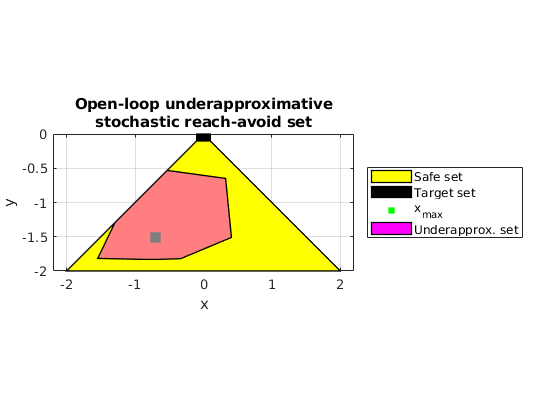

figure();
hold on;
plot(safe_set.slice([3,4], slice_at_vx_vy), 'color', 'y');
plot(target_set.slice([3,4], slice_at_vx_vy), 'color', 'k');

scatter(xmax(1), xmax(2), 100,'gs','filled')
if ~isEmptySet(underapproximate_stochastic_reach_avoid_polytope)
    plot(underapproximate_stochastic_reach_avoid_polytope_2D,...
         'color','m','alpha',0.5);
    leg=legend({'Safe set',...
            'Target set',...
            'x_{max}',...
            'Underapprox. set'});
else
    leg=legend({'Safe set','Target set', 'x_{max}'})
end
set(leg,'Location','EastOutside');
xlabel('x')
ylabel('y')
axis equal;
box on;
grid on;
title(sprintf('Open-loop underapproximative\nstochastic reach-avoid set'));

## Validate the underapproximative set and the controllers synthesized using Monte-Carlo simulations

We will now check how the optimal policy computed for each corners perform in Monte-Carlo simulations.

Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.822
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.816
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.807
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.807
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.807
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.814
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.814
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.814
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.811
Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.800, 0.822


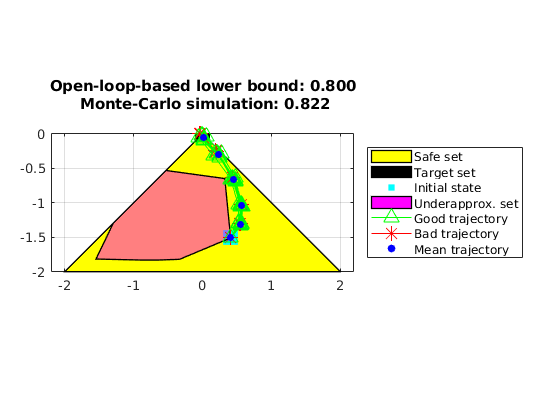

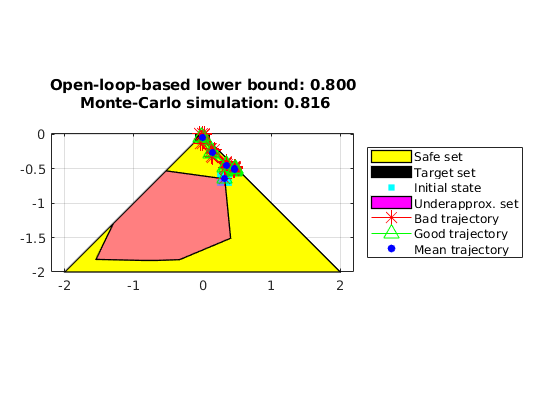

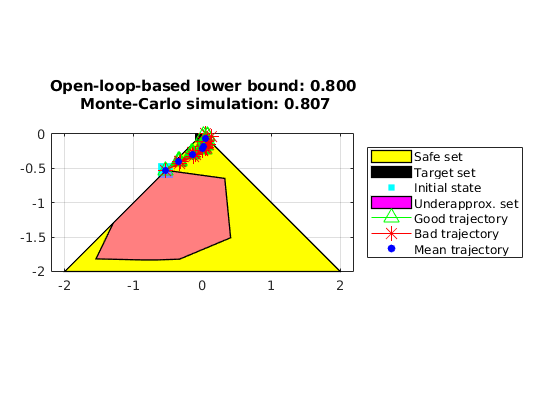

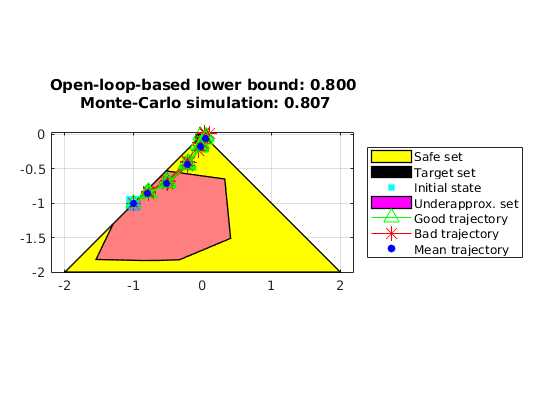

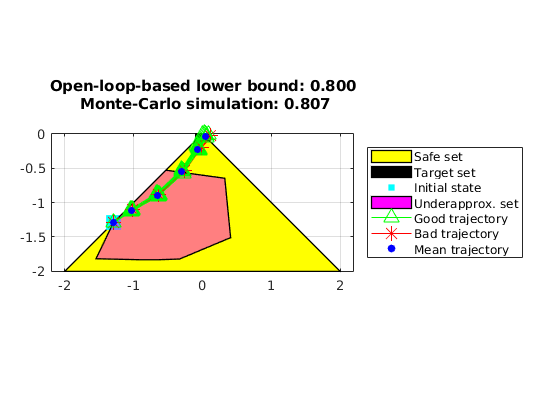

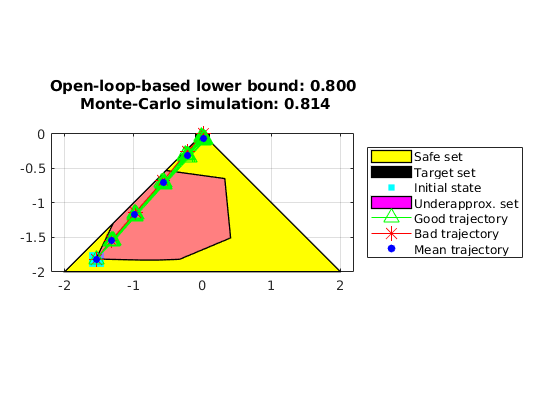

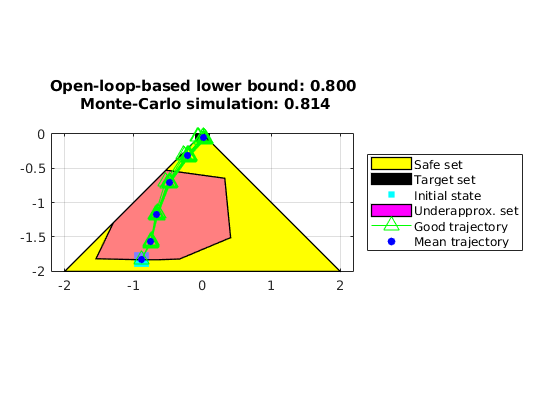

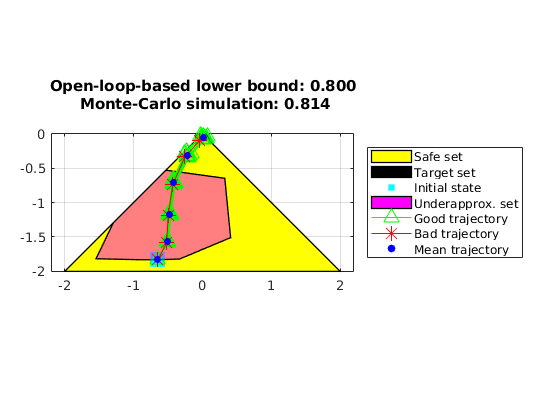

if ~isEmptySet(underapproximate_stochastic_reach_avoid_polytope)
    for direction_index = 1:no_of_direction_vectors
        figure();
        hold on;
        plot(safe_set.slice([3,4], slice_at_vx_vy), 'color', 'y');
        plot(target_set.slice([3,4], slice_at_vx_vy), 'color', 'k');
        scatter(vertex_poly(1,direction_index),...
                vertex_poly(2,direction_index),...
                200,'cs','filled');
        plot(underapproximate_stochastic_reach_avoid_polytope_2D,...
             'color','m','alpha',0.5);
        legend_cell = {'Safe set',...
                       'Target set',...
                       'Initial state',...
                       'Underapprox. set'};
        concat_state_realization = generateMonteCarloSims(...
                                       n_mcarlo_sims,...
                                       sys,...
                                       vertex_poly(:,direction_index),...
                                       time_horizon,...
                                       optimal_input_vector_at_boundary_points(:,direction_index));
        % Check if the location is within the target_set or not
        mcarlo_result = target_tube.contains(concat_state_realization);
        %% Plot n_sims_to_plot number of trajectories
        green_legend_updated = 0;
        red_legend_updated = 0;
        traj_indices = floor(n_mcarlo_sims*rand(1,n_sims_to_plot));
        for realization_index = traj_indices
            % Check if the trajectory satisfies the reach-avoid objective
            if mcarlo_result(realization_index)
                % Assign green triangle as the marker
                markerString = 'g^-';
            else
                % Assign red asterisk as the marker
                markerString = 'r*-';
            end
            % Create [x(t_1) x(t_2)... x(t_N)]
            reshaped_X_vector = reshape(concat_state_realization(:,realization_index), sys.state_dim,[]);
            % This realization is to be plotted
            h = plot([vertex_poly(1,direction_index), reshaped_X_vector(1,:)], ...
                     [vertex_poly(2,direction_index), reshaped_X_vector(2,:)], ...
                     markerString, 'MarkerSize',10);
            % Update the legends if the first else, disable
            if strcmp(markerString,'g^-')
                if green_legend_updated
                    h.Annotation.LegendInformation.IconDisplayStyle = 'off';
                else
                    green_legend_updated = 1;
                    legend_cell{end+1} = 'Good trajectory';
                end
            elseif strcmp(markerString,'r*-')
                if red_legend_updated
                    h.Annotation.LegendInformation.IconDisplayStyle = 'off';
                else
                    red_legend_updated = 1;
                    legend_cell{end+1} = 'Bad trajectory';
                end
            end
        end    
        % Compute and plot the mean trajectory under the optimal open-loop
        % controller from the the vertex under study
        [H_matrix, mean_X_sans_input, ~] =...
         getHmatMeanCovForXSansInput(sys,...
                                     vertex_poly(:,direction_index),...
                                     time_horizon);
        optimal_mean_X = mean_X_sans_input + H_matrix *...
                    optimal_input_vector_at_boundary_points(:, direction_index);
        optimal_mean_trajectory=reshape(optimal_mean_X,sys.state_dim,[]);
        % Plot the optimal mean trajectory from the vertex under study
        scatter(...
              [vertex_poly(1,direction_index), optimal_mean_trajectory(1,:)],...
              [vertex_poly(2,direction_index), optimal_mean_trajectory(2,:)],...
              30, 'bo', 'filled');
        legend_cell{end+1} = 'Mean trajectory';
        leg = legend(legend_cell,'Location','EastOutside');
        % title for the plot
        title(sprintf(['Open-loop-based lower bound: %1.3f\n Monte-Carlo ',...
                           'simulation: %1.3f\n'],...
                optimal_reachAvoid_i(direction_index),...
                sum(mcarlo_result)/n_mcarlo_sims));
        box on;
        grid on;
        axis equal

        fprintf(['Open-loop-based lower bound and Monte-Carlo simulation ',...
                 '(%1.0e particles): %1.3f, %1.3f\n'],...
                n_mcarlo_sims,...
                optimal_reachAvoid_i(direction_index),...
                sum(mcarlo_result)/n_mcarlo_sims);
    end
end